# PRACTICA 9

## **Sistmeas diferenciales y en diferencias**

Para sistemas diferenciales realiza un programa con las siguientes características

- Muestra la función de transferencia del sistema

- Muestra la respuesta al impulso (simbólico, gráfica)

- Muestra la respuesta a entrada cero (simbólico, gráfica)

- Muestra la respuesta a estado cero (simbólico, gráfica)

- Muestra la respuesta total (simbólico, gráfica)

- La respuesta total al escalón con condiciones iniciales 0 (simbólico, gráfica)

- Usando subplot, depliega una figura con 5 gráficas

Se utliza el código para resolver EDs con Laplace de la [página](https://rafneta.github.io/PracticasSyS/20201/P06ASyS20201/P06ASyS20201.html) de la práctica


syms t;

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
X(s) - s X(s)

 
LA FUNCIÓN DE TRANSFERENCIA DE LA ECUACIÓN DIFERENCIAL ES:
 
H(s)=
 
LA RESPUESTA AL IMPULSO ES
 
h(t)=


$$ans = -\frac{s-1}{s^{2}+2\,s-1}$$

$$h(t) = -{\mathrm{e}}^{-t}\,\left(\cosh\left(\sqrt{2}\,t\right)-\sqrt{2}\,\sinh\left(\sqrt{2}\,t\right)\right)$$

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                         2
3 Y(s) - s + 3 s Y(s) + s  Y(s) - 4

=
            2
   s       s
------ - ------
 2        2
s  + 4   s  + 4

 
DESPEJAMOS Y(s)
 
Y(s)=
     3      2
    s  + 3 s  + 5 s + 16
----------------------------
 4      3      2
s  + 3 s  + 7 s  + 12 s + 12

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
 50 s   142    13 s    8
 ---- + ---    ---- - --
  37     37     37    37
------------ - ---------
 2                2
s  + 3 s + 3     s  + 4

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
                                        /                               / sqrt(3) t \    \
                                        |                    sqrt(3) sin| --------- | 67 |
                              /   3 t \ |    / sqrt(3) t \              \     2     /    |
                           exp| - --- | | cos| --------- | + --------------------------- | 50
sin(2 t) 4   cos(2 t) 13      \    2  / \   

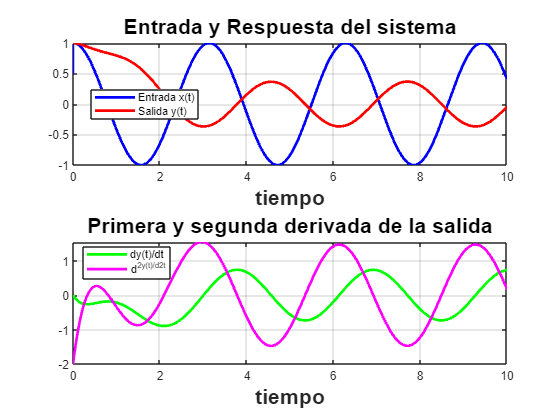

SEDLaplace([3,3,1],[1,-1],[1,1],cos(2*t)*heaviside(t),10)